# Model, Visualize, and Analyze Satellite Scenario

This example shows how to model satellites in orbit, analyze access between the satellites and the ground stations, and visualize the fields of view and ground tracks of the satellites.

## Create Satellite Scenario

Create a satellite scenario with the start time of 02-June-2020 8:23:00 AM UTC and a stop time of five hours later. Set the simulation sample time to `60` seconds. 

startTime = datetime(2020,6,02,8,23,0);
stopTime = startTime + hours(5);
sampleTime = 60;
sc = satelliteScenario(startTime,stopTime,sampleTime);

## Add Satellites to Scenario

Add satellites to the scenario from the `threeSatelliteConstellation` TLE file.

sat = satellite(sc,"threeSatelliteConstellation.tle");

Show the satellites in orbit and plot their ground tracks over 20 minutes.

show(sat)
groundTrack(sat,"LeadTime",1200);

## Return Orbital Elements and Position of Satellites

Display the orbital elements of each satellite in the scenario.

ele1 = orbitalElements(sat(1))

ele1 = struct with fields:
                       MeanMotion: 0.0525
                     Eccentricity: 1.0000e-03
                      Inclination: 55
    RightAscensionOfAscendingNode: 175.0000
              ArgumentOfPeriapsis: 100
                      MeanAnomaly: 174.9900
                           Period: 6.8557e+03
                            Epoch: 02-Jun-2020 18:43:16
                            BStar: 1.0000e-04


ele2 = orbitalElements(sat(2))

ele2 = struct with fields:
                       MeanMotion: 0.0487
                     Eccentricity: 1.0000e-03
                      Inclination: 55
    RightAscensionOfAscendingNode: 350.0000
              ArgumentOfPeriapsis: 90
                      MeanAnomaly: 310.0877
                           Period: 7.3898e+03
                            Epoch: 02-Jun-2020 18:33:26
                            BStar: 1.0000e-04


ele3 = orbitalElements(sat(3))

ele3 = struct with fields:
                       MeanMotion: 0.0496
                     Eccentricity: 1.0000e-03
                      Inclination: 55
    RightAscensionOfAscendingNode: 270
              ArgumentOfPeriapsis: 95
                      MeanAnomaly: 119.9007
                           Period: 7.2550e+03
                            Epoch: 02-Jun-2020 18:37:40
                            BStar: 1.0000e-04


Return the latitude, longitude, and altitude of the first satellite at time 02-June-2020 12:30:00 PM UTC.

time = datetime(2020,6,02,12,30,0);
pos = states(sat(1),time,"CoordinateFrame","geographic")

pos = 1.0e+06 *

    0.0000
   -0.0001
    1.4212


## Add Ground Stations

Specify the latitudes and longitudes of the Madrid and Canberra Deep Space Communications Complexes as ground stations of interest. 

name = ["Madrid Deep Space Communications Complex", ...
      "Canberra Deep Space Communications Complex"];
lat = [40.43139, -35.40139];
lon = [-4.24806, 148.98167];
gs = groundStation(sc,"Name",name,"Latitude",lat, ...
    "Longitude", lon);

## Return Azimuth Angle, Elevation Angle, and Range at Specified Time

Return the azimuth angle, elevation angle and range of the first satellite with respect to the Madrid Deep Space Communications Complex at time 02-June-2020 12:30:00 PM UTC.

time = datetime(2020,6,02,12,30,0);
[az,elev,r] = aer(gs(1),sat(1),time)

az = 264.2457

elev = -34.0669

r = 9.3088e+06

Play the satellite scenario with the satellites and ground stations.

play(sc)

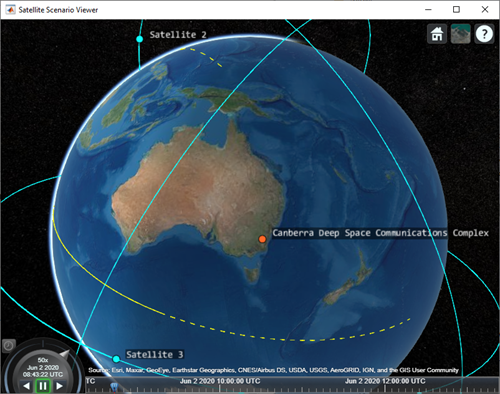

*Copyright 2022 The MathWorks, Inc.*